clc;
clear all;
close all;

filename='RCS_custom_drone.csv';
data= readtable(filename);

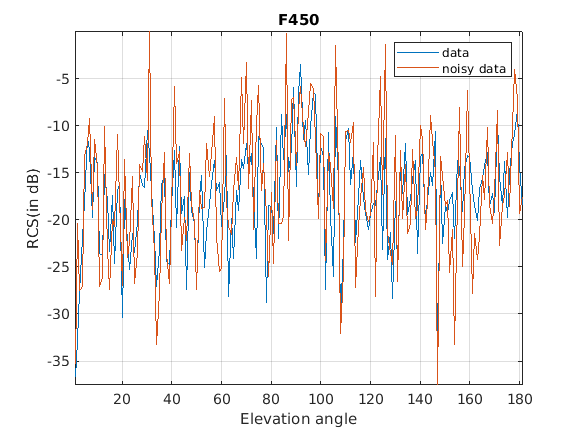


xd= data.RCS_dB_;
y = reshape(xd,[],4);
dn = awgn(xd,10,'measured');
n = reshape(dn,[],4);
x=1:1:181;
x=x.';
plot(x,y(:,1)); title('F450');grid on; axis tight;
hold on;plot(n(:,1));legend('data','noisy data');xlabel('Elevation angle'),ylabel('RCS(in dB)');

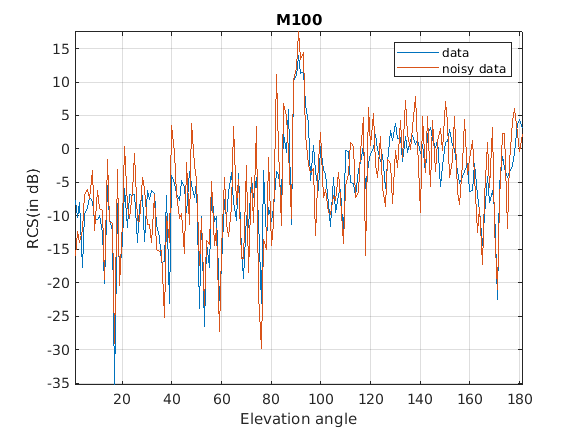

figure;
plot(x,y(:,2));title('M100');grid on; axis tight;
hold on;plot(n(:,2));legend('data','noisy data');xlabel('Elevation angle'),ylabel('RCS(in dB)');

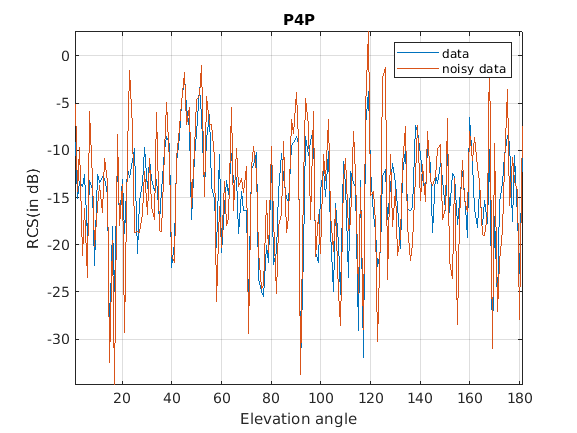

figure;
plot(x,y(:,3));title('P4P');grid on; axis tight;
hold on;plot(n(:,3));legend('data','noisy data');xlabel('Elevation angle'),ylabel('RCS(in dB)');

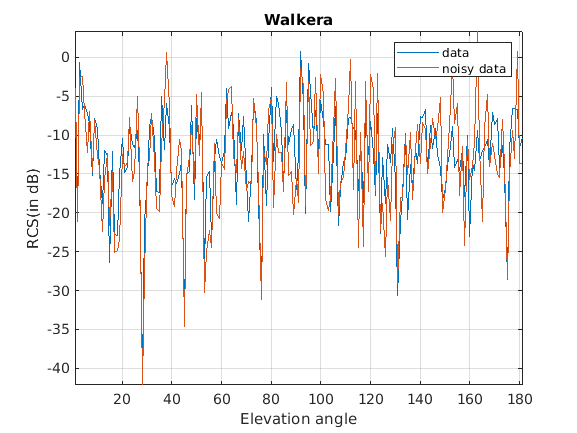

figure;
plot(x,y(:,4));title('Walkera');grid on; axis tight;xlabel('Elevation angle'),ylabel('RCS(in dB)');
hold on;plot(n(:,4));legend('data','noisy data');

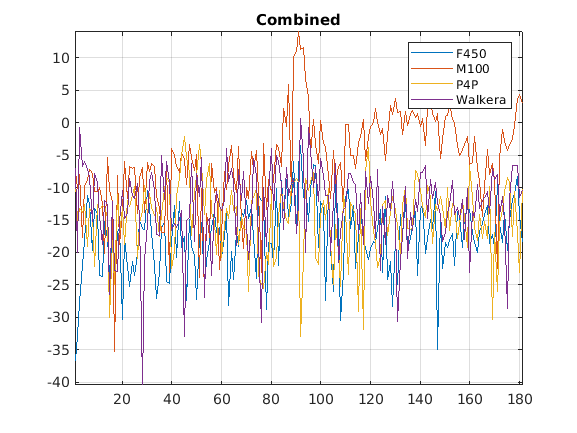


figure;
plot(y(:,1));hold on;plot(y(:,2));plot(y(:,3));plot(y(:,4));title('Combined');grid on; axis tight;
legend('F450','M100','P4P','Walkera');